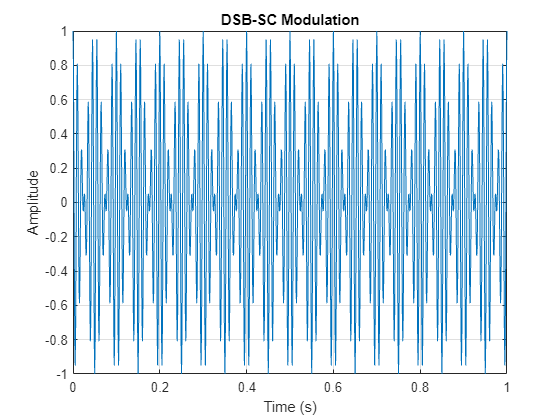

% MATLAB code for DSBSC , SSB and VSB 

% Parameters
t = 0:0.001:1;   % Time vector from 0 to 1 second with 1 ms steps
fc = 100;        % Carrier frequency in Hz
fm = 10;         % Message signal frequency in Hz
Ac = 1;          % Carrier amplitude
Am = 1;          % Message signal amplitude

% Generate message signal
m = Am * cos(2*pi*fm*t);

% DSB-SC Modulation
dsbsc = m .* cos(2*pi*fc*t);

% SSB Modulation (Hilbert Transform method)
ssb = hilbert(m) .* exp(1i*2*pi*fc*t);

% VSB Modulation (VSB with carrier)
vsb = m .* cos(2*pi*fc*t) + imag(hilbert(m)) .* sin(2*pi*fc*t);

% Plotting
figure;

%subplot(3,1,1);
plot(t, dsbsc);
title('DSB-SC Modulation');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

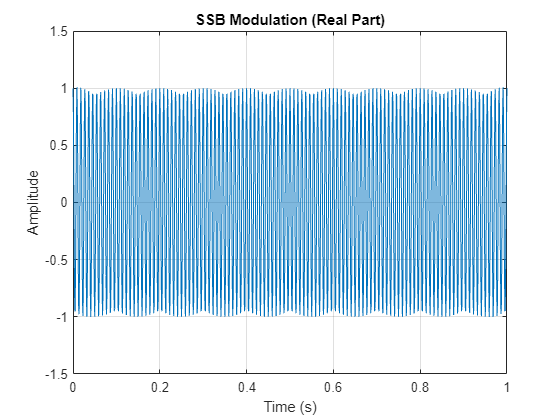


%subplot(3,1,2);
plot(t, real(ssb));
title('SSB Modulation (Real Part)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

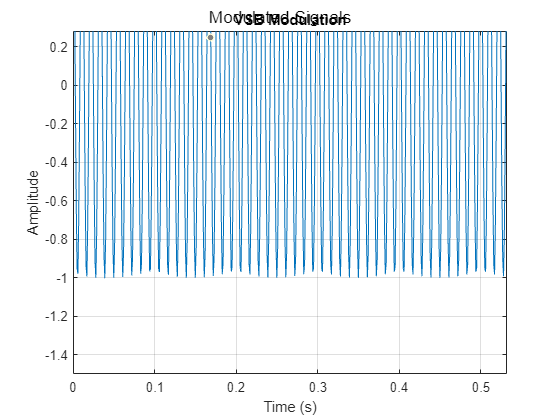


%subplot(3,1,3);
plot(t, vsb);
title('VSB Modulation');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

sgtitle('Modulated Signals');